load("stiffness_matrix_2d.mat","A");
load("load_vector_2d.mat","fh");
dim = 2;
num_elem = sqrt(length(A))/2-1;
num_elem_min = 4;

## V-cycle

gs_iter = 10; mg_iter = 10;

uh = zeros(length(fh),1);
tic;
% uh = tg(A,fh,gs_iter,mg_iter);
for i=1:mg_iter
    uh = v_cycle(A,fh,uh,gs_iter,num_elem,num_elem_min);
end
toc;

Elapsed time is 0.027564 seconds.


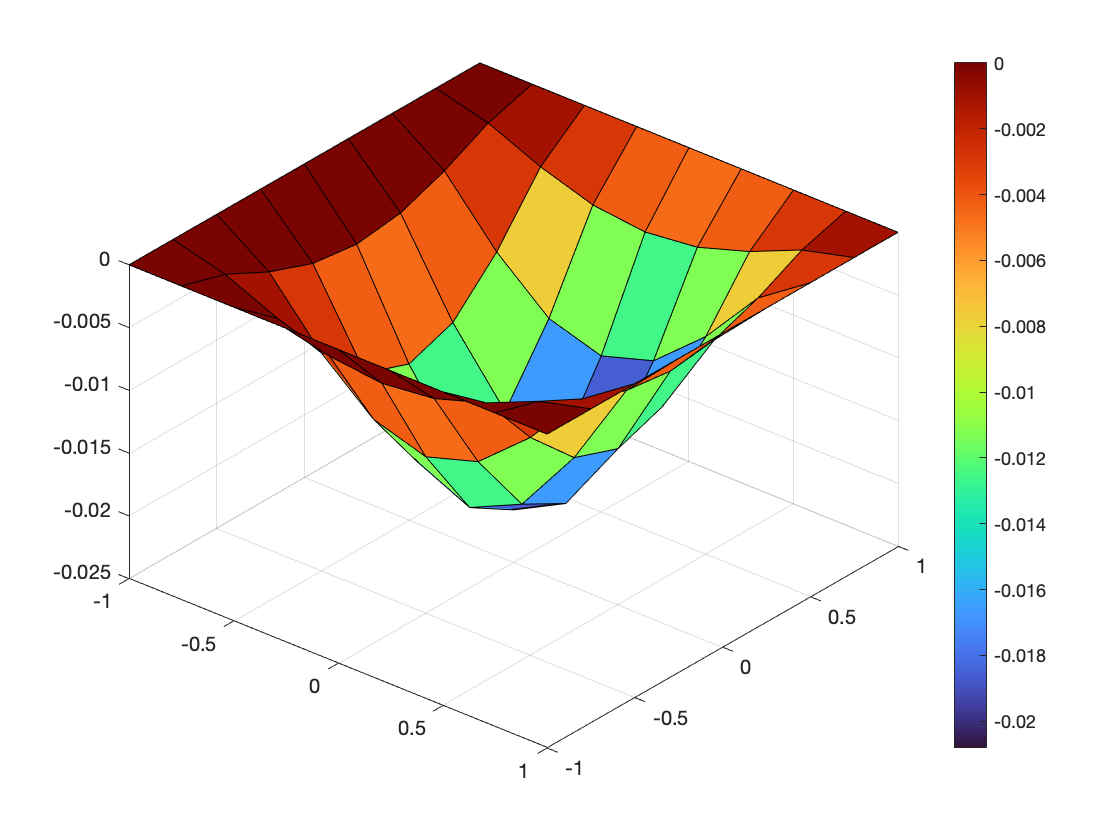

xmin = -1; xmax = 1;
ymin = -1; ymax = 1;
F = -1;
xdim = num_elem+1;
ydim = num_elem+1;
Uh = zeros(xdim, ydim);

for i=1:ydim
    for j=1:xdim
        n1 = (i-1)*(xdim) + (j-1) + 1;
        n = 4*n1-3;
        Uh(j,i) = uh(n);
    end
end

xs = linspace(xmin,xmax,xdim);
ys = linspace(ymin,ymax,ydim);

[X,Y] = meshgrid(xs,ys);
surf(X,Y,Uh')
zlim([min(0, 0.025*F) max(0,0.025*F)])
colormap turbo
colorbar
view([40 40])

u_exact = A \ fh;

disp(max(abs(u_exact-uh)))

     7.630632276569432e-06



function [P,scaling] = interp_mat(Nel,dim)
    % connectivity
    Pcon = zeros(2*Nel+1,Nel+1);
    for i=1:Nel+1
        Pcon(2*i-1,i) = 1;
        if i < Nel+1
            Pcon(2*i,i:i+1) = .5;
        end
    end
    Pcon = sparse(Pcon);
    % adjustment for the number of dof per node
    P = sparse(Pcon);
    for i=1:dim-1
        P = kron(P,Pcon);
    end
    P = kron(P,eye(2^dim));
    avg_col_sum = rms(sum(P),2);
    scaling = avg_col_sum(1);
end

function u = gs(A,f,u0,niter)
    L = tril(A,0);
    U = triu(A,1);
    u = u0;
    for i=1:niter
        u = L\(f-U*u);
    end
end

function dirichlet = diri_nodes(N, dim)
    if dim == 1
        dirichlet = [1;N+1];
    elseif dim == 2
        dirichlet = zeros(4*N,1);
        for i=1:N+1
            dirichlet(i) = i;
        end
        for i=1:N-1
            dirichlet(N+1+i) = (N+1)*(i+1);
        end
        for i=1:N+1
            dirichlet(2*N+i) = (N+1)*N+i;
        end
        for i=1:N-1
            dirichlet(3*N+1+i) = (N+1)*(i)+1;
        end
    end
end

function A = set_diri_A(A,N,dim)
    dirichlet = diri_nodes(N,dim);
    lenA = length(A);
    if dim == 1
        A(1:2,:) = 0; A(:,1:2) = 0; A(1,1) = 1; A(2,2) = 1;
        A(end-1:end,:) = 0; A(:,end-1:end) = 0; A(end-1,end-1) = 1; A(end,end) = 1;
    elseif dim == 2
        M = N;
        for i = 1:length(dirichlet)
            diri = dirichlet(i);
            if i == 1 || i == N+1 || i == N+1+M || i==N+1+M+N 
                % corners 
                % only u is prescribed
                diri_full = [4*diri-3];
                numcond = 1;
            elseif (i > 1 && i < N+1) || (i > N+1+M && i < N+1+M+N)
                % bottom and top walls
                % u and u_y prescribed
                diri_full = [4*diri-3 4*diri-1];
                numcond = 2;
            else 
                % left and right walls
                % u and u_x prescribed
                diri_full = [4*diri-3 4*diri-2];
                numcond = 2;
            end
            % replace rows and columns with canonical vectors
            A(diri_full,:) = zeros(numcond, lenA);
            A(:,diri_full) = zeros(lenA, numcond);
            for j=1:numcond
                A(diri_full(j), diri_full(j)) = 1;
            end
        end
    end
end

function fh = set_diri_fh(fh,N,dim)
    dirichlet = diri_nodes(N,dim);
    if dim == 1
        fh(1:2) = 0; fh(end-1:end) = 0;
    elseif dim == 2
        M = N;
        for i = 1:length(dirichlet)
            diri = dirichlet(i);
            if i == 1 || i == N+1 || i == N+1+M || i==N+1+M+N 
                % corners 
                % only u is prescribed
                diri_full = [4*diri-3];
                numcond = 1;
            elseif (i > 1 && i < N+1) || (i > N+1+M && i < N+1+M+N)
                % bottom and top walls
                % u and u_y prescribed
                diri_full = [4*diri-3 4*diri-1];
                numcond = 2;
            else 
                % left and right walls
                % u and u_x prescribed
                diri_full = [4*diri-3 4*diri-2];
                numcond = 2;
            end
            fh(diri_full) = zeros(numcond,1);
        end
    end
end

function u_tg = tg(A,fh,gs_iter,mg_iter)
    num_elem = sqrt(length(A))/2-1;
    num_elem2h = num_elem/2;
    [P,scaling] = interp_mat(num_elem2h,2);
    
    u0 = zeros(length(fh),1);
    uh = u0;
    
    A2h = 1/scaling*P'*A*P;
    A2h = set_diri_A(A2h,num_elem2h,2);
    
    for i=1:mg_iter
        uh = gs(A,fh,uh,gs_iter);
        rh = fh - A*uh;

        r2h = P'*rh;
        r2h = set_diri_fh(r2h,num_elem2h,2);
        e2h = A2h\r2h;
        
        eh = P*e2h;
        uh = uh + eh;
        uh = gs(A,fh,uh,gs_iter);
    end
    u_tg = uh;
end

function u_v = v_cycle(A,fh,uh,gs_iter,num_elem,Nmin)
    num_elem2h = num_elem/2;
    
    [P,scaling] = interp_mat(num_elem2h,2);
    
    A2h = 1/scaling*P'*A*P;
    A2h = set_diri_A(A2h,num_elem2h,2);
    
    uh = gs(A,fh,uh,gs_iter);
    rh = fh - A*uh;

    r2h = P'*rh;
    r2h = set_diri_fh(r2h,num_elem2h,2);
    
    if num_elem <= Nmin
        e2h = A2h\r2h;
    else
        e2h = zeros(length(r2h),1);
        e2h = v_cycle(A2h,r2h,e2h,gs_iter,num_elem2h,Nmin);
    end
    
    eh = P*e2h;
    uh = uh + eh;
    uh = gs(A,fh,uh,gs_iter);
    
    u_v = uh;
end